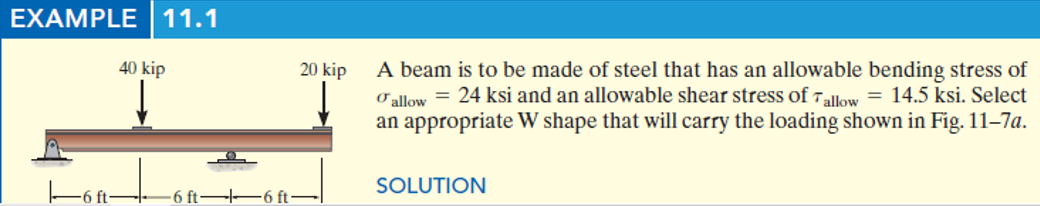

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# allowable stresses

sigma_allow = 24*u.ksi;
tau_allow = 14.5*u.ksi;

# beam

b = beam;
b = b.add('reaction', 'force', 'R1', 0);
b = b.add('reaction', 'force', 'R2', 12*u.ft);
b = b.add('concentrated', 'force', -40*u.kip, 6*u.ft);
b = b.add('concentrated', 'force', -20*u.kip, 18*u.ft);
b.L = 18*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(72\,{\mathrm{ft}}^{2}-x^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{5\,\left(x-12\,\mathrm{ft}\right)\,\left(x^{2}-12\,x\,\mathrm{ft}+24\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{10\,\left(x-12\,\mathrm{ft}\right)\,\left(x^{2}-42\,x\,\mathrm{ft}+324\,{\mathrm{ft}}^{2}\right)}{3\,\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(24\,{\mathrm{ft}}^{2}-x^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{15\,\left(x^{2}-16\,x\,\mathrm{ft}+56\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{10\,\left(x^{2}-36\,x\,\mathrm{ft}+276\,{\mathrm{ft}}^{2}\right)}{\text{E}\,\text{I}}\,\mathrm{kip} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 10\,x\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -30\,\left(x-8\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ 20\,\left(x-18\,\mathrm{ft}\right)\,\mathrm{kip} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 10\,\mathrm{kip} & \text{ if }x\leq 6\,\mathrm{ft}\\ -30\,\mathrm{kip} & \text{ if }x\in \left(6\,\mathrm{ft},12\,\mathrm{ft}\right]\\ 20\,\mathrm{kip} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra 

$$ra = \left(\begin{array}{cc} R_{1} & 10\,\mathrm{kip}\\ R_{2} & 50\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

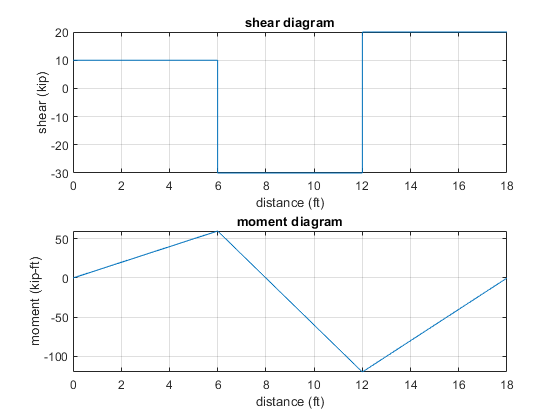

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# required section modulus

M_max = -m(12*u.ft);
S.reqd = rewrite(M_max/sigma_allow, u.in);
S_reqd = S.reqd %#ok<NASGU> 

$$S\_reqd = 60\,{\mathrm{in}}^{3}$$

# design section modulus

% Appendix B table
t = beam.appendixB('fps');
Model = t.Properties.CustomProperties.Model;
Weight = t.Properties.CustomProperties.Weight;
Designation = t.Properties.RowNames;
% minimum beam weight
in_range = isAlways(t.Sx*u.in^3 >= S.reqd);
Weight_min = symmin(Weight(in_range));
Model_min = Model(Weight == Weight_min & in_range);
min_loc = isAlways(Model == Model_min & ...
                   Weight == Weight_min & ...
                   in_range);
Designation_min = Designation{min_loc}

Designation_min = 'W18 x 40'

% design section modulus
S.design = t.Sx(Designation_min)*u.in^3;
S_design_vpa = vpa(S.design) %#ok<NASGU> 

$$S\_design\_vpa = 68.4\,{\mathrm{in}}^{3}$$

# maximum shear stress

V_max = -v(8*u.ft);
d = t.Depth(Designation_min)*u.in;
tw = t.Web_Thickness(Designation_min)*u.in;
Aw = d*tw;
tau_max = rewrite(V_max/Aw, u.ksi);
tau_max_vpa = vpa(tau_max, 3) %#ok<NASGU> 

$$tau\_max\_vpa = 5.32\,\mathrm{ksi}$$

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear S_reqd;
clear S_design_vpa;
clear tau_max_vpa;
clear old_assum;